# Coordinate-invariant rigid-body interpolation on a parametric C1 dual quaternion curve

Authors: Felix Allmendinger (KUKA), Sami Charaf Eddine (RWTH), Burkhard Corves (RWTH)

Link: [https://www.sciencedirect.com/science/article/abs/pii/S0094114X17312119](https://www.sciencedirect.com/science/article/abs/pii/S0094114X17312119)

## 0. Contributions of the paper

- Invariant interpolation of in-between orientations during linear spherical interpolation (slerp)

- Smooth ($C^1$) cubical interpolation for multiple key frames

- Invariant interpolation of in-between displacements during cubical spherical interpolation with screws (sclerp)

## I. Motivation

- Computer animations

- (Robotic) Path planning 

- Post processing of measurements ($T_{\text{Sensor}} \neq T_{\text{Ctrl}}$)

### Key frames

The term "key frame interpolation" is used in computer animation. Key frames are images of transforming objects and the associated timesteps created.

In robotic language: We attach a (body-fixed) coordinate frame on the rigid body and continously describe the pose of the body with respect to a spatial (world-fixed) coordinate frame. 

### Interpolation of 3D-positions

- $x,y,z$-coordinates are uncoupled

- Can be interpolated independently

- Constant linear velocity on the shortest path

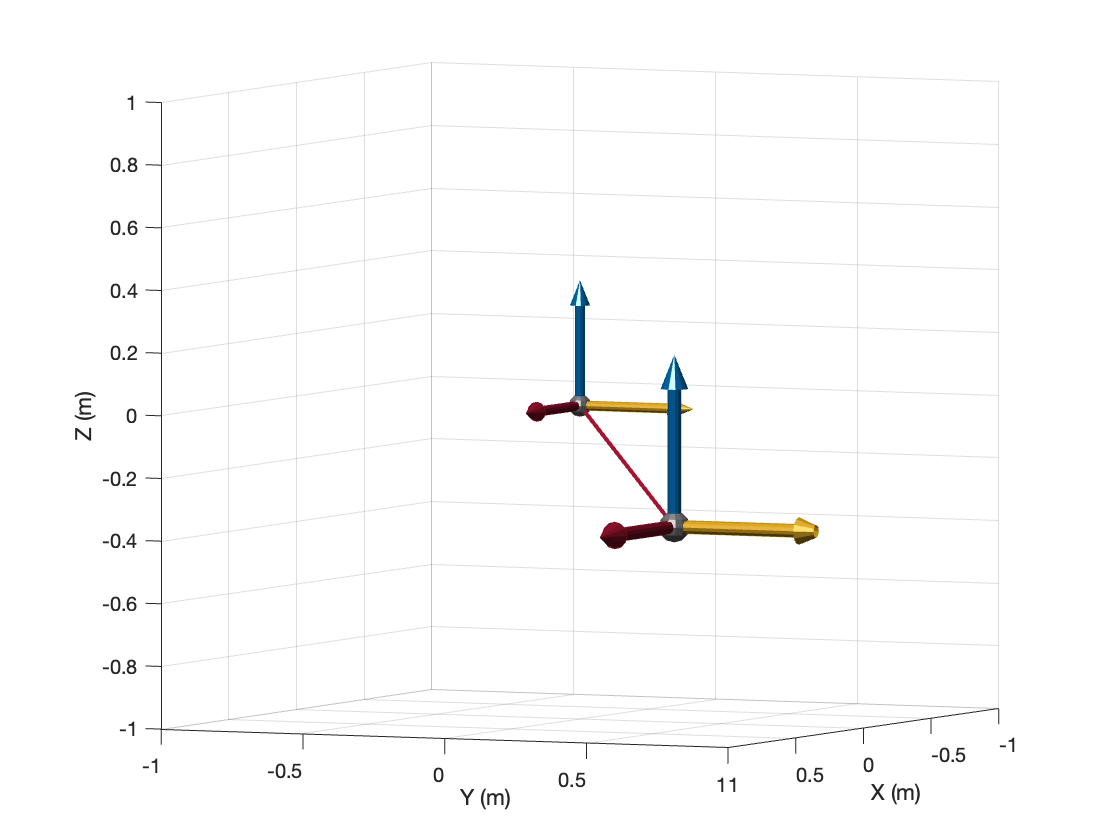

%% This script should show the linear interpolating of position
% Author: Johannes Lachner
% Date: October 4, 2022

% Clean up
close all;
clc;

% Include sub-folder
func_addSubfolders('helpers');

% Make a figure
x_lim = [ -1 1 ];
y_lim = [ -1 1 ];
z_lim = [ -1 1 ];
[fig, ax] = func_createFigure(x_lim, y_lim, z_lim);
view(110,10);                                   % aspect ratio

% Traceplots
tracePlot_x = plot3(NaN, NaN, NaN);
set(tracePlot_x, 'XData', [], 'YData',[], 'ZData', []);
tracePlot_y = plot3(NaN, NaN, NaN);
set(tracePlot_y, 'XData', [], 'YData',[], 'ZData', []);
tracePlot_z = plot3(NaN, NaN, NaN);
set(tracePlot_z, 'XData', [], 'YData',[], 'ZData', []);

% Create initial coordinate frame
H_0_ini = eye(4);
H_0 = H_0_ini;
angles_ini = rotm2eul(H_0_ini(1:3, 1:3), 'ZYX');   % Convert transformation matrix to Euler angles
hg_1 = hgtransform('Parent', ax, 'Matrix',  H_0_ini);
[V1,F1,C1] = func_create_VFC_data('CoordinateSys',12);
V1 = 0.4 * V1;
patchTCP1 = patch('Faces', F1,...
    'Vertices' ,V1,...
    'FaceVertexCData', C1,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_1);

% Goal translation
X = 0.35;               % Translation along x
Y = 0.5;                % Translation along y
Z = -0.35;                  % Translation along z
H_0_des = H_0_ini;
H_0_des(1:3, 4) = H_0_ini(1:3, 4) + [X , Y, Z]';

% Create interpolated coordinate frame
hg_2 = hgtransform('Parent', ax, 'Matrix', H_0_des);
[V2,F2,C2] = func_create_VFC_data('CoordinateSys',12);
V2 = 0.55 * V2;
patchTCP2 = patch('Faces', F2,...
    'Vertices' ,V2,...
    'FaceVertexCData', C2,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_2);

% Create goal sphere
hg_3 = hgtransform('Parent', ax, 'Matrix', H_0_des);
[V3,F3,C3] = func_create_VFC_data('Sphere',2);
V3 = 0.05 * V3;
patchTCP2 = patch('Faces', F3,...
    'Vertices' ,V3,...
    'FaceVertexCData', C3,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_3);

%% Simulation
curTime = 0;
Tstep = 2;
dt = 0.005;
while curTime <= Tstep
    tic

    % Linear interpolator of position
    ratio = curTime / Tstep;
    if ratio > 1
        ratio = 1.0;
    end
    H_0(1:3, 4) = H_0_ini(1:3, 4) + ratio * ( H_0_des(1:3, 4) - H_0_ini(1:3, 4) );     

    % Update current coordinate system
    set(hg_2, 'Matrix', H_0);
    
    view([115.52 4.00])

    % TRACEPLOTS
    % x-coordinate
    curX_x = get(tracePlot_x, 'XData');
    curY_x = get(tracePlot_x, 'YData');
    curZ_x = get(tracePlot_x, 'ZData');

    set(tracePlot_x, 'XData', [curX_x, H_0(1, 4)], ...
        'YData', [curY_x, H_0(2, 4)], ...
        'ZData', [curZ_x, H_0(3, 4)], 'Color', [0.6350 0.0780 0.1840], 'LineStyle', '-', 'LineWidth', 2 );

    % Update simulation
    drawnow
    curTime = curTime + dt;

    while toc < dt
        % do nothing
    end
end

### Description of orientation

The geometric orientation of an object can be described by

- [Rotation matrices](https://en.wikipedia.org/wiki/Rotation_matrix): (3, 3)-matrices; Rows and columns are dependent, i.e., ${\mathit{\mathbf{R}}}^{\;T} \mathit{\mathbf{R}}=\mathit{\mathbf{I}};\;\det \left(\mathit{\mathbf{R}}\right)=1$ 

- [Euler angles](https://en.wikipedia.org/wiki/Euler_angles): (3, 1)-triple (not a vector!); Describe consecutive rotations, e.g., first about $x$, then about $y$, then about $z$

- Axis and angle: Based on [Euler's rotation theorem](https://en.wikipedia.org/wiki/Euler%27s_rotation_theorem) (1776)--any rotation about 3 axes can be expressed as one rotation $\theta \;$about a space-fixed axis $\mathit{\mathbf{u}}$($\textrm{eig}\left(R\right)$)

### Linear interpolation between orientation descriptions

- Rotation matrix: Matrix elements cannot be interpolated, because ${\mathit{\mathbf{R}}}^{\;T} \mathit{\mathbf{R}}=\mathit{\mathbf{I}};\;\det \left(\mathit{\mathbf{R}}\right)=1$will be violated

- Euler angles (also: Cardan angles, Roll-Pitch-Yaw): 

                Elements can be interpolated

                ... but may lead to unexpected results!

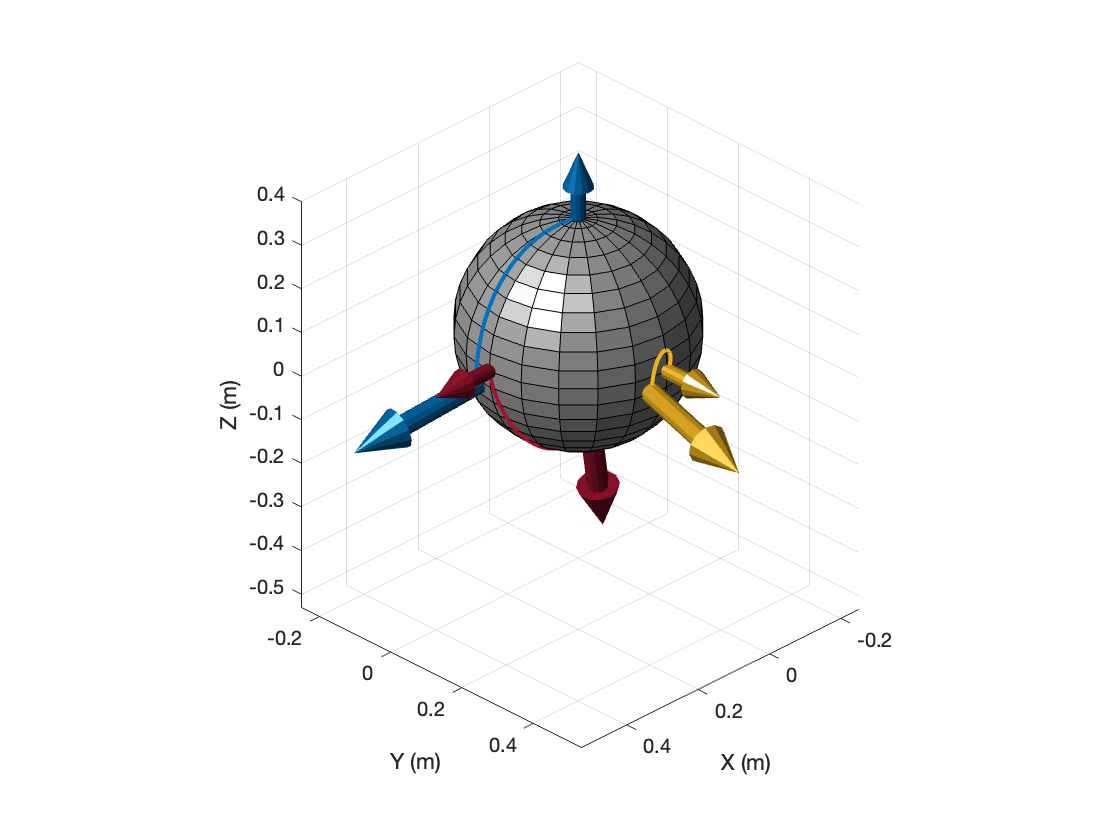

%% This script should show uncoupled Euler angles during linear interpolation
% Author: Johannes Lachner
% Date: October 4, 2022

% Clean up
clc;
clf;

% Include sub-folder
func_addSubfolders('helpers');

% Make a figure
x_lim = [ -1 1 ];
y_lim = [ -1 1 ];
z_lim = [ -1 1 ];
[fig, ax] = func_createFigure(x_lim, y_lim, z_lim);

% Create sphere
[x , y, z ] = sphere;
hold on;
radius = 0.25;
x = x * radius;
y = y * radius;
z = z * radius;
axis equal;
surf(x, y, z, 'FaceColor', [.7 .7 .7])

% Points of intersection between initial coordinate system and sphere surface
p_x_ini = [radius, 0 , 0]';
p_y_ini = [0, radius, 0]';
p_z_ini = [0, 0, radius]';

% Initial transformation
H_0_ini = eye(4);
angles_ini = [0, 0, 0];

% Goal transformation
angles_goal = deg2rad( [25, 105, 35] );
H_0_des = eul2tform(angles_goal, 'ZYX');


%% Plot data
% Initial key frame
hg_1 = hgtransform('Parent', ax, 'Matrix',  H_0_ini);
[V1,F1,C1] = func_create_VFC_data('CoordinateSys',12);
V1 = 0.4 * V1;
patchTCP1 = patch('Faces', F1,...
    'Vertices' ,V1,...
    'FaceVertexCData', C1,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_1);

% Goal key frame
hg_2 = hgtransform('Parent', ax, 'Matrix', H_0_des);
[V2,F2,C2] = func_create_VFC_data('CoordinateSys',12);
V2 = 0.55 * V2;
patchTCP2 = patch('Faces', F2,...
    'Vertices' ,V2,...
    'FaceVertexCData', C2,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_2);

% Traceplots
tracePlot_x = plot3(NaN, NaN, NaN);
set(tracePlot_x, 'XData', [], 'YData',[], 'ZData', []);
tracePlot_y = plot3(NaN, NaN, NaN);
set(tracePlot_y, 'XData', [], 'YData',[], 'ZData', []);
tracePlot_z = plot3(NaN, NaN, NaN);
set(tracePlot_z, 'XData', [], 'YData',[], 'ZData', []);

%% Simulation
curTime = 0;
Tstep = 2;
dt = 0.005;
while curTime <= Tstep
    tic

    % Linear interpolator of Euler angles
    ratio = curTime / Tstep;
    if ratio > 1
        ratio = 1.0;
    end
    angles = angles_ini + ratio * (angles_goal - angles_ini);     

    % Convert Euler angles to transformation matrix
    H_0_des = eul2tform(angles, 'ZYX');

    % Update current coordinate system
    set(hg_2, 'Matrix', H_0_des);

    % TRACEPLOTS
    % x-coordinate
    curX_x = get(tracePlot_x, 'XData');
    curY_x = get(tracePlot_x, 'YData');
    curZ_x = get(tracePlot_x, 'ZData');

    p_x = H_0_des(1:3 , 1:3) * p_x_ini;
    set(tracePlot_x, 'XData', [curX_x, p_x(1)], ...
        'YData', [curY_x, p_x(2)], ...
        'ZData', [curZ_x, p_x(3)], 'Color', [0.6350 0.0780 0.1840], 'LineStyle', '-', 'LineWidth', 2 );

    % y-coordinate
    curX_y = get(tracePlot_y, 'XData');
    curY_y = get(tracePlot_y, 'YData');
    curZ_y = get(tracePlot_y, 'ZData');

    p_y = H_0_des(1:3 , 1:3) * p_y_ini;
    set(tracePlot_y, 'XData', [curX_y, p_y(1)], ...
        'YData', [curY_y, p_y(2)], ...
        'ZData', [curZ_y, p_y(3)], 'Color', [0.9290 0.6940 0.1250], 'LineStyle', '-', 'LineWidth', 2 );

    % z-coordinate
    curX_z = get(tracePlot_z, 'XData');
    curY_z = get(tracePlot_z, 'YData');
    curZ_z = get(tracePlot_z, 'ZData');

    p_z = H_0_des(1:3 , 1:3) * p_z_ini;
    set(tracePlot_z, 'XData', [curX_z, p_z(1)], ...
        'YData', [curY_z, p_z(2)], ...
        'ZData', [curZ_z, p_z(3)], 'Color', [0 0.4470 0.7410], 'LineStyle', '-', 'LineWidth', 2 );

    % Update simulation
    drawnow
    curTime = curTime + dt;

    while toc < dt
        % do nothing
    end
end

                "Consecutive" rotations: Coordinates are not uncoupled!

                Angular velocity cannot be controlled

                [Gimbal lock](https://en.wikipedia.org/wiki/Gimbal_lock): non-orthogonal axes coincide and one rotational degree of freedom is lost

- Axis and angle

                Compute the (space-fixed) axis $\mathit{\mathbf{u}}$and the rotation angle $\theta {\;}_{\textrm{des}}$

                Linear interpolation is linearly increasing angle $\theta_{\textrm{des}} \left(t\right)$ about fixed axis $\mathit{\mathbf{u}}$

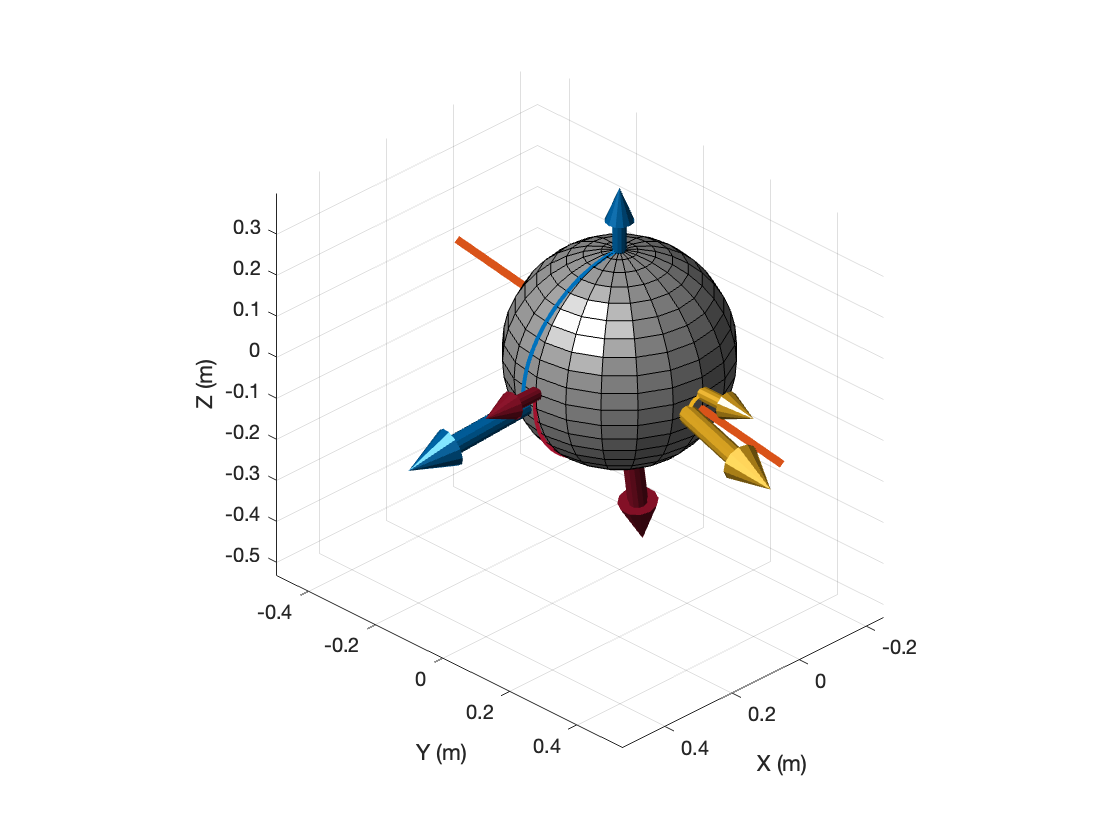

%% A simple linear interpolator of axis angle
% Author: Johannes Lachner
% Date: October 4, 2022

% Clean up
clc;
clf;

% Include sub-folder
func_addSubfolders('helpers');

% Make a figure
x_lim = [ -1 1 ];
y_lim = [ -1 1 ];
z_lim = [ -1 1 ];
[fig, ax] = func_createFigure(x_lim, y_lim, z_lim);

% Create sphere
[x , y, z ] = sphere;
hold on;
radius = 0.25;
x = x * radius;
y = y * radius;
z = z * radius;
axis equal;
surf(x, y, z, 'FaceColor', [.7 .7 .7])

% Points of intersection between initial coordinate system and sphere surface
p_x_ini = [radius, 0 , 0]';
p_y_ini = [0, radius, 0]';
p_z_ini = [0, 0, radius]';

% Initial transformation
H_0_ini = eye(4);

% Goal transformation
H_0_des = eul2tform(deg2rad( [25, 105, 35] ), 'ZYX');

% Orientation between initial and desired
H_ini_0 = H_0_ini\eye(size(H_0_ini));                            % inverse transformation  
H_ini_des = H_ini_0 * H_0_des;
axang = rotm2axang(H_ini_des(1:3, 1:3));
u = axang(1:3);
theta_goal = axang(4);
theta_ini = 0;

% Plot (space-fixed) axis u
X = [-u(1)/2, u(1)/2]';
Y = [-u(2)/2, u(2)/2]';
Z = [-u(3)/2, u(3)/2]';
plot3(X, Y, Z, 'LineWidth', 4, 'Color', [0.8500 0.3250 0.0980]);

%% Plot data
% Initial key frame
hg_1 = hgtransform('Parent', ax, 'Matrix',  H_0_ini);
[V1,F1,C1] = func_create_VFC_data('CoordinateSys',12);
V1 = 0.4 * V1;
patchTCP1 = patch('Faces', F1,...
    'Vertices' ,V1,...
    'FaceVertexCData', C1,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_1);

% Goal key frame
hg_2 = hgtransform('Parent', ax, 'Matrix', H_0_des);
[V2,F2,C2] = func_create_VFC_data('CoordinateSys',12);
V2 = 0.55 * V2;
patchTCP2 = patch('Faces', F2,...
    'Vertices' ,V2,...
    'FaceVertexCData', C2,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_2);

% Traceplots
tracePlot_x = plot3(NaN, NaN, NaN);
set(tracePlot_x, 'XData', [], 'YData',[], 'ZData', []);
tracePlot_y = plot3(NaN, NaN, NaN);
set(tracePlot_y, 'XData', [], 'YData',[], 'ZData', []);
tracePlot_z = plot3(NaN, NaN, NaN);
set(tracePlot_z, 'XData', [], 'YData',[], 'ZData', []);

%% Simulation
curTime = 0;
Tstep = 2;
dt = 0.005;
while curTime <= Tstep
    tic
 
    % Some random linear interpolator 
    ratio = curTime / Tstep;
    if ratio > 1
        ratio = 1.0;
    end
    theta = theta_ini + ratio * (theta_goal - theta_ini);

    % Convert axis/angle to transformation matrix
    axang(4) = theta;
    H_0_des(1:3, 1:3) = axang2rotm(axang);

    % Update current coordinate system
    set(hg_2, 'Matrix', H_0_des);

    % TRACEPLOTS
    % x-coordinate
    curX_x = get(tracePlot_x, 'XData');
    curY_x = get(tracePlot_x, 'YData');
    curZ_x = get(tracePlot_x, 'ZData');

    p_x = H_0_des(1:3 , 1:3) * p_x_ini;
    set(tracePlot_x, 'XData', [curX_x, p_x(1)], ...
        'YData', [curY_x, p_x(2)], ...
        'ZData', [curZ_x, p_x(3)], 'Color', [0.6350 0.0780 0.1840], 'LineStyle', '-', 'LineWidth', 2 );

    % y-coordinate
    curX_y = get(tracePlot_y, 'XData');
    curY_y = get(tracePlot_y, 'YData');
    curZ_y = get(tracePlot_y, 'ZData');

    p_y = H_0_des(1:3 , 1:3) * p_y_ini;
    set(tracePlot_y, 'XData', [curX_y, p_y(1)], ...
        'YData', [curY_y, p_y(2)], ...
        'ZData', [curZ_y, p_y(3)], 'Color', [0.9290 0.6940 0.1250], 'LineStyle', '-', 'LineWidth', 2 );

    % z-coordinate
    curX_z = get(tracePlot_z, 'XData');
    curY_z = get(tracePlot_z, 'YData');
    curZ_z = get(tracePlot_z, 'ZData');

    p_z = H_0_des(1:3 , 1:3) * p_z_ini;
    set(tracePlot_z, 'XData', [curX_z, p_z(1)], ...
        'YData', [curY_z, p_z(2)], ...
        'ZData', [curZ_z, p_z(3)], 'Color', [0 0.4470 0.7410], 'LineStyle', '-', 'LineWidth', 2 );

    % Update simulation
    drawnow
    curTime = curTime + dt;

    while toc < dt
        % do nothing
    end
end

### How

- Given: $^{\text{ini}}\textbf{R}_{\text{des}} = \ ^{\text{ini}}\textbf{R}_{0} \ ^{\text{0}}\textbf{R}_{\text{des}}$

- With $^{\text{ini}}\textbf{R}_{\text{des}}$, compute $\mathit{\mathbf{u}}$ and the rotation angle $\theta {\;}_{\textrm{des}}$

- Interpolate $0\;\le \theta \;\le \theta {\;}_{\textrm{des}}$

- (Rotate back to 0-coordinates if needed)

## II. Mathematical background

Quaternions are the direct implementation of [Euler's formula](https://en.wikipedia.org/wiki/Euler%27s_formula). They open up a new type of algebra: *quaternion algebra*.

**Complex number**

A 2D-vector $\mathbf{v}=\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack$ can be expressed as a complex number: $\textbf{v} = x + iy, \text{with} \ i^2 = -1 $

With Euler's formula $e^{i\theta } =\cos \left(\theta \right)+i\;\sin \left(\theta \right)$, $\textbf{v}$ can be rotated by multiplication with another complex number: $\text{Rot}(\textbf{v}) = e^{i \theta} \textbf{v}$

**Quaternions** 

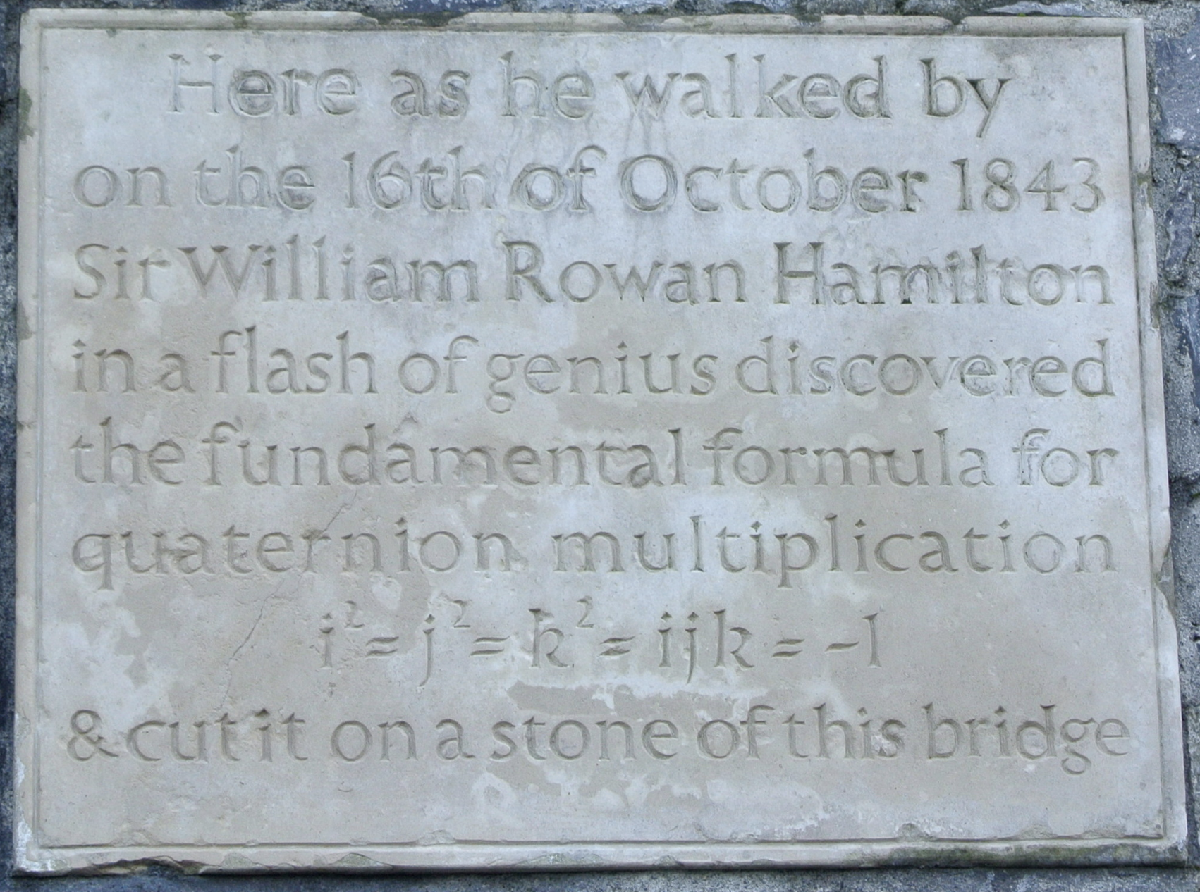

[Hamilton](https://en.wikipedia.org/wiki/William_Rowan_Hamilton) (Monday, 16 October 1843): To similarly rotate a 3D-vector, we need three complex units $i, j, k$.

- $\mathcal{q}$$=\left\lbrack \begin{array}{c}
s\\
v_1 i\\
v_2 j\\
v_3 k
\end{array}\right\rbrack \;,$ with Euler parameters $s,v_1 ,v_2 ,v_3$ and $i^2 =j^{\;2} =k^2 =i\;j\;k=-1$

- $\text{Rot}(\textbf{v}) = \textbf{R} \textbf{v} = \mathcal{q}^{-1} $$\left\lbrack \begin{array}{c}
0\\
\mathit{\mathbf{v}}
\end{array}\right\rbrack$$\mathcal{q}$ (conjugation)

- Unit-length constraint to represent spherical displacement on unit-sphere: $\mathcal{q}^T \mathcal{q} = 1$ (from now on called "quaternions")

- Euler's formula: $\mathcal{q}$= $\cos \left(\frac{\;\theta \;\;}{2}\right)+\mathit{\mathbf{u}}\;\sin \left(\frac{\;\theta \;}{2}\right)=e^{\mathit{\mathbf{u}}\;\frac{\theta \;}{2}}$ (angle $\frac{\;\theta \;}{2}$ due to conjugation)

- Exponential and logarithmic map: $\mathcal{q} = e^{\text{log}(\mathcal{q})} \rightarrow \text{log}(\mathcal{q}) = \textbf{u} \frac{\theta}{2}$

- Rules for addition, multiplication, inverse ([**C**]**ANI ADDU**)

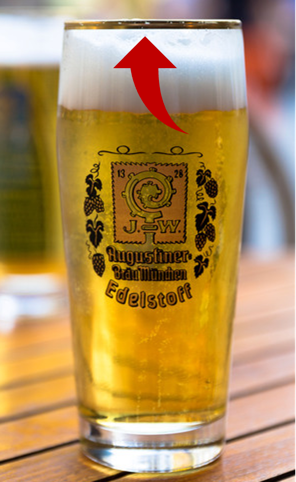

[**Slerp**](https://en.wikipedia.org/wiki/Slerp)

**         S**pherical **L**inear Int**erp**olation: $\mathcal{q}(t) = \text{slerp}(\mathcal{q}_1, \mathcal{q}_2; t) = \mathcal{q}_1 \ {(\mathcal{q}_1^{-1} \ \mathcal{q}_2)}^{t}$ for $0 \leq t \leq 1$

- The term $\mathcal{q}_1^{-1} \ \mathcal{q}_2$ gives the angular displacement $\textbf{u}_{1 \rightarrow 2}, \theta_{1 \rightarrow 2}$ between the two key frames.

- Constant rotation axis through exponent $t$:

                                         
$$\mathcal{q}^t = e^{(t \ \text{log}(\mathcal{q}))} = e^{\textbf{u} \ \frac{t \theta }{2}} = \text{cos}(\frac{t \theta}{2}) + \textbf{u} \ \text{sin}(\frac{t \theta}{2}) $$


- Gradual increase of the angle about a fixed axis

- Result is a [geodesic](https://en.wikipedia.org/wiki/Geodesic) between $\mathcal{q}_1$and $\mathcal{q}_2$ (shortest path in a curved space)

- We can linearly interpolate the orientation

- Constant angular velocity along the shortest path

- This is a $\mathit{C}^0$ continuous solution

- Implementation ([MATLAB](https://de.mathworks.com/help/nav/ref/quaternion.slerp.html)): $\text{slerp}(\mathcal{q}_1, \mathcal{q}_2; t) = \frac{\sin(1 - t) \theta}{\sin(\theta)} \mathcal{q}_1 + \frac{\sin(t\theta)}{\sin(\theta)} \mathcal{q}_2 $

- Be careful: $\mathcal{q}^{-1} $$\left\lbrack \begin{array}{c}
0\\
\mathit{\mathbf{v}}
\end{array}\right\rbrack$$\mathcal{q}$$=$$(-\mathcal{q}^{-1} )$$\left\lbrack \begin{array}{c}
0\\
\mathit{\mathbf{v}}
\end{array}\right\rbrack$$-\mathcal{q} \rightarrow $ $\mathcal{q} $ and$-\mathcal{q} $ represent the same rotation

## III. Interpolation

### Interpolation of position

- Linear interpolation of position: 

                Mathematically: $x(t) = k_0 + k_1 t, \text{with} \ 0 \leq t \leq 1$            

                Geometrically: $x(t) = \text{lin} (x_0, x_1, t)$

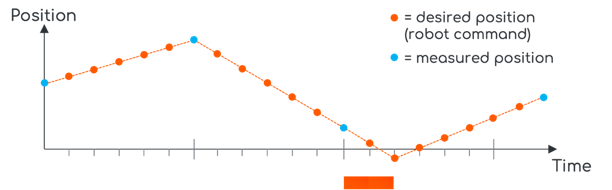

- Cubic interpolation of position

                Mathematically: $x(t) = k_0 + k_1 t + k_2 t^2 + k_3 t^3, \text{with} \ 0 \leq t \leq 1$

                Geometrically: $x(t) = \text{lin} \ ( (  \ \text{lin} \ (\text{lin}(x_0, a, t) , \text{lin}(a, b, t) , t) \ ,  \ \text{lin} \ (\text{lin}(a, b, t) , \text{lin}(b, x_1, t) \ , t) \ , t)$

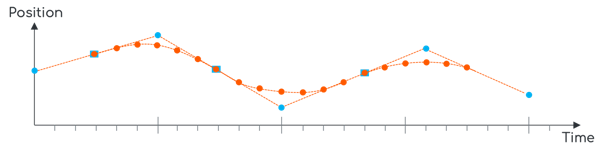

- Iteration of linear operations

- This is [Casteljeau’s algorithm](https://en.wikipedia.org/wiki/De_Casteljau%27s_algorithm) for Bézier curves

- Four coordinates needed: $x_0, x_1, a , b$ 

- Less important for now, how to find $a, b$?

- Very important: this works for quaternions, too $\to$Because slerp is linear interpolation!

### Cubic interpolation between two quaternions

- Given: two "key" quaternions $\mathcal{q}_1$ and $\mathcal{q}_2$

- Compute the two "control quaternions" $\mathcal{q}_a$ and $\mathcal{q}_b$ (please refer to the Matlab code)

- For $0 \leq t \leq 1: $

                    
$$\mathcal{q}(t) = \text{slerp}  \ (  \ \text{slerp} \ (\text{slerp}(\mathcal{q}_1, \mathcal{q}_a, t) , \text{slerp}(\mathcal{q}_a, \mathcal{q}_b, t) , t) \ ,  \ \text{slerp} \ (\text{slerp}(\mathcal{q}_a, \mathcal{q}_b, t) , \text{slerp}(\mathcal{q}_b, \mathcal{q}_2, t)  , t) \ , t \ )$$


- Continuous in angular velocity ($C^1$)

- Control over angular velocity through control quaternions (these couple translational and rotational motion)

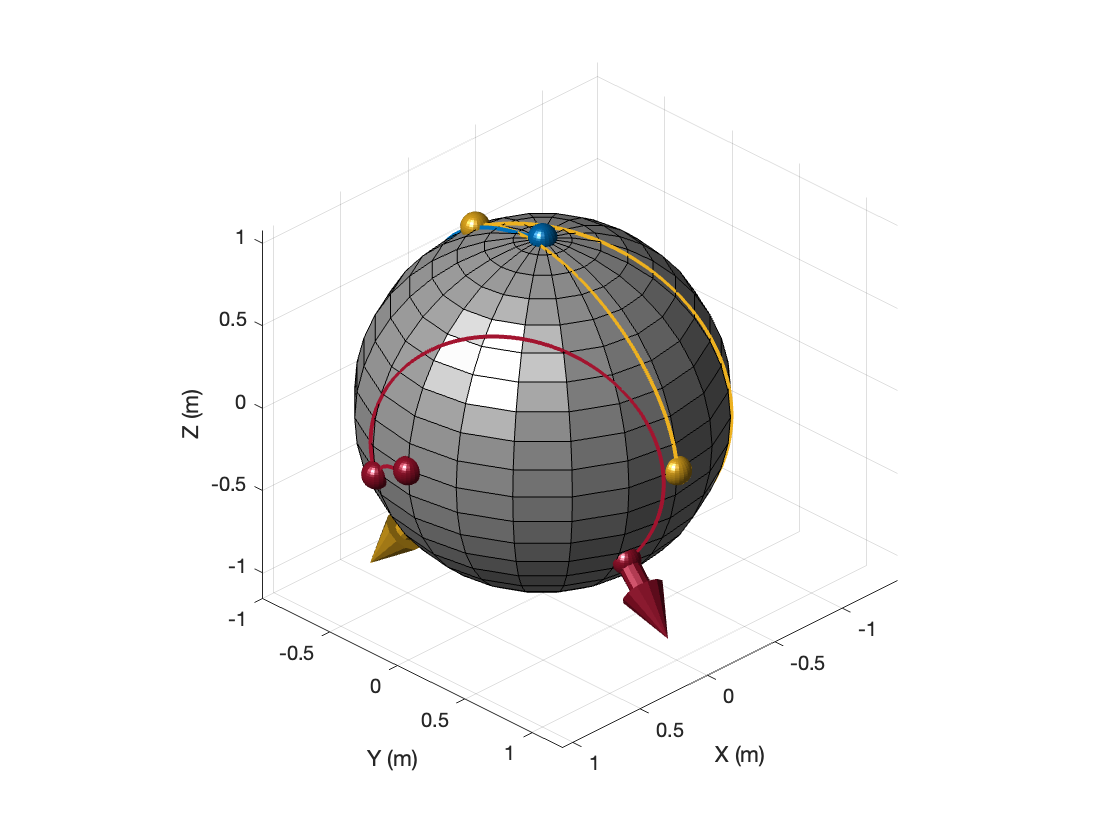

%% Cubic interpolation with slerp
% Author: Johannes Lachner
% Date: October 4, 2022

% Clean up
clc;
clf;

% Include subdirectories
func_addSubfolders('helpers');

% Make a figure
x_lim = [-1, 1];
y_lim = [-1.5, 1.5];
z_lim = [-1, 2];
[fig, ax] = func_createFigure(x_lim, y_lim, z_lim);

% Create sphere
[x , y, z ] = sphere;
hold on;
axis equal;
surf(x, y, z, 'FaceColor', [.7 .7 .7])

%% Supporting points and tangent vectors
no_keys = 3;
no_segs = no_keys-1;

x = NaN(3, no_keys);
q = NaN(4, no_keys);
xS = NaN(3, no_keys);

x(:,1) = deg2rad([0, 0, 0]');
x(:,2) = deg2rad([120, -20, 0]');
x(:,3) = deg2rad([0, 250, -235]');

for cur_key = 1:no_keys
    rot = eul2rotm(x(:,cur_key)', 'XYZ');
    q(:,cur_key) = rotm2quat(rot);
end
q = func_restrictQuatsOnHemisphere(q);

% Angular velocities expressed in spatial coordinate frame
omega(:,1) = [1, 1, 0]' * 0.5;
omega(:,2) = [-1, 0.5, 0]';
omega(:,3) = [2, 0.5, 0]' * 0.5;

%% Plot Initial key frame
hg_1 = hgtransform('Parent', ax, 'Matrix',  eye(4));
[V1,F1,C1] = func_create_VFC_data('CoordinateSys',12);
V1 = 1.5 * V1;
framePlotCubic = patch('Faces', F1,...
    'Vertices' ,V1,...
    'FaceVertexCData', C1,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_1);

%% C1 cubic interpolation

% Interpolation settings
dt = 0.001;
T = 0:dt:1;

% Initialize quaternions
q00 = q(:,1:end-1);
q01 = NaN(4,no_segs);
q02 = NaN(4,no_segs);
q03 = q(:,2:end);

% Use key angular key velocities to compute control quats
for cur_seg = 1:no_segs
    % Transform key velocities to key systems
    omega_key_n = Quat_mult( Quat_mult( Quat_inv( q(:,cur_seg)) , [0; omega(:,cur_seg)] ) , q(:,cur_seg) );
    omega_key_np1 = Quat_mult( Quat_mult( Quat_inv( q(:,cur_seg+1) ) , [0; omega(:,cur_seg+1)] ) , q(:,cur_seg+1) );

    q01(:,cur_seg) = Quat_mult( q(:,cur_seg) , Quat_exp(1/3 * 1/2 * omega_key_n) );
    q02(:,cur_seg) = Quat_mult( q(:,cur_seg+1) , Quat_exp(-1/3 * 1/2 * omega_key_np1) );
end

q_ges = [];
s_ges = [];

for cur_seg = 1:no_segs
    C = func_CubBez4D([q00(:,cur_seg), q01(:,cur_seg), q02(:,cur_seg), q03(:,cur_seg)], T);
    s_inc = T;
    if cur_seg ~= no_segs        % unless this is the last segment
        C(:,end) = [];           % remove the last element (=first element of next segment)
        s_inc(:,end) = [];
    end
    q_ges = [q_ges, C];
    s_ges = [s_ges, (cur_seg-1) + s_inc];
end

%% Animate cubic interpolation
func_Plot_Quats_on_unit_sphere(q_ges, q, '-', gcf);

H_0_cur = eye(4);
for cur_step = 1:3:length(s_ges)
    H_0_cur(1:3, 1:3) = quat2rotm(q_ges(:,cur_step)');
    set(hg_1, 'Matrix', H_0_cur)
    drawnow;
    pause(0.01);
end

## IV. Coordinate independence

Coordinate independence: A transformation of the body-fixed **or** the spatial coordinate frame does not change the in-between results of interpolation.

- Rotation of the spatial coordinate frame (left translation): 

             Given $^{S_1}\mathcal{q}_1 \ ^{S_2}\mathcal{q}_1, \ ^{S_1}\mathcal{q}_2, \ ^{S_2}\mathcal{q}_2, \ ^{S_2}\mathcal{q}_{S_1} = \mathcal{p},$

                                            
$$\text{slerp}(\mathcal{p} \mathcal{q}_{1}, \mathcal{p} \mathcal{q}_{2}, t) = ... = \mathcal{p} \text{slerp}(\mathcal{q}_{1}, \mathcal{q}_{2}, t)$$


- Rotation of the body-fixed coordinate frame (right translation): 

             Given $^{S}\mathcal{q}_{B_1}, \ ^{S}\mathcal{q}__{B_2}, \ ^{S}\mathcal{q}__{A_1},  \ ^{S}\mathcal{q}_{A_2}, \ ^{A}\mathcal{q}_B = \mathcal{p},$

                                            
$$\text{slerp}(\mathcal{q}_{1} \mathcal{p},  \mathcal{q}_{2} \mathcal{p}, t) = ... = \text{slerp}(\mathcal{q}_{1}, \mathcal{q}_{2}, t) \mathcal{p} $$


$\rightarrow \text{slerp}$is bi-invariant on coordinate change. This makes sense since the relative angle remains untouched.

However: In-between rigid-body poses do not have the same displacement

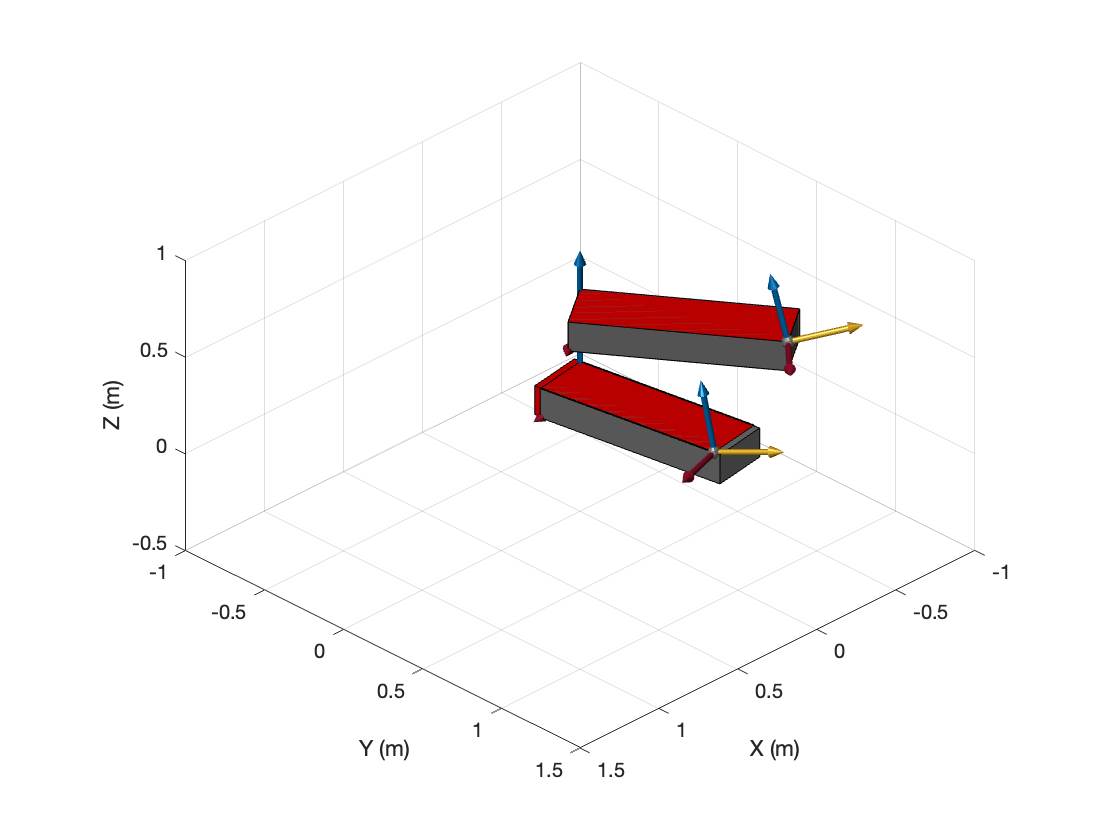

%% Interpolation with slerp to show displacements of body-fixed coordinate frames
% Author: Johannes Lachner
% Date: October 4, 2022

% Clean up
clc;
clf;

% Include subdirectories
func_addSubfolders('helpers');

% Make a figure
x_lim = [-1, 1.5];
y_lim = [-1, 1.5];
z_lim = [-0.5, 1];
[fig, ax] = func_createFigure(x_lim, y_lim, z_lim);

% Initialize interpolated transformation matrices
H_0_cur1 = eye(4);
H_0_cur2 = eye(4);

% Initial and final coordiantes for coordinate frame 1
H_0_ini1 = eye(4);                                                       % Initial transformation of frame 1 is identity
q1_ini = quaternion(H_0_ini1(1:3, 1:3), 'rotmat', 'frame');              % Initial orientation of frame 1 is identity

q1_goal = quaternion([35, 0, 0],'eulerd','ZYX','frame');                 % Goal orientation frame 1
p1_goal = [0 , 0, 0.5]';                                                 % Goal translation frame 1 (along z)
H_0_goal1 = quat2tform(q1_goal);
H_0_goal1(1:3, 4) = p1_goal;

% Initial and final coordiantes for coordinate frame 2
H_0_ini2 = eul2tform(deg2rad( [12, -4, 13] ), 'ZYX');
H_0_ini2(1, 4) = 0.3;                                                    % Move along long side of box
H_0_ini2(2, 4) = 1;                                                      % Move along depth of box
H_0_ini2(3, 4) = 0.15;                                                   % Move along height of box
q2_ini = quaternion([12, -4, 13],'eulerd','ZYX','frame');  

% x = A\b is computed differently than x = inv(A)*b
H_0_ini1_inv = H_0_ini1\eye(size(H_0_ini1));
H_1_2 = H_0_ini1_inv * H_0_ini2;                                        % Transformation between two coordinate frames

H_0_goal2 = H_0_goal1 * H_1_2;
q2_goal = quaternion(H_0_goal2(1:3, 1:3)', 'rotmat', 'frame');           % Goal orientation of frame 2            
p2_goal = H_0_goal2(1:3, 4);                                             % Goal translation of frame 2

%% Plot data: Coordinate frames and boxes

% Draw interpolated coordinate frame 1
hg_1 = hgtransform('Parent', ax, 'Matrix', H_0_ini1);
[V1,F1,C1] = func_create_VFC_data('CoordinateSys',12);
V1 = 0.35 * V1;
patchTCP1 = patch('Faces', F1,...
    'Vertices' ,V1,...
    'FaceVertexCData', C1,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_1);

% Draw interpolated coordinate frame 2
hg_2 = hgtransform('Parent', ax, 'Matrix', H_1_2);
[V2,F2,C2] = func_create_VFC_data('CoordinateSys',12);
V2 = 0.35 * V2;
patchTCP2 = patch('Faces', F2,...
    'Vertices' ,V2,...
    'FaceVertexCData', C2,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_2);

% Create box and set parent hg_1 (interpolated coordinate frame 1)
hg_1B = hgtransform('Parent', hg_1, 'Matrix', eye(4));
[v1,f1,c1] = func_create_VFC_data('Box', 12);
patchBox1 = patch('Vertices',v1,...
    'Faces',f1,...
    'FaceVertexCData',c1,...
    'FaceColor','flat',...
    'Parent', hg_1B);

% Create box and set parent hg_2 (interpolated coordinate frame 2)
hg_2B = hgtransform('Parent', hg_2, 'Matrix', inv(H_0_ini2));
[v2,f2,c2] = func_create_VFC_data('Box', 14);
patchBox2 = patch('Vertices',v2,...
    'Faces',f2,...
    'FaceVertexCData',c2,...
    'FaceColor','r',...
    'Parent', hg_2B);



%% Simulation
curTime = 0;
Tstep = 1;
dt = 0.005;
step = 1;
while curTime <= Tstep
    tic

    % Interpolate quaternions
    quat1 = slerp(q1_ini, q1_goal, curTime);
    quat2 = slerp(q2_ini, q2_goal, curTime);

    % Linear interpolator of position
    ratio = curTime / Tstep;
    if ratio > 1
        ratio = 1.0;
    end
    p_0_1 = H_0_ini1(1:3, 4) + ratio * ( p1_goal - H_0_ini1(1:3, 4) );
    p_0_2 = H_0_ini2(1:3, 4) + ratio * ( p2_goal - H_0_ini2(1:3, 4) );

    % Convert to transformation matrix
    H_0_cur1(1:3, 1:3) = quat2rotm(quat1);
    H_0_cur1(1:3, 4) = p_0_1;
    H_0_cur2(1:3, 1:3) = quat2rotm(quat2);
    H_0_cur2(1:3, 4) = p_0_2;

    % Update key frame
    set(hg_1, 'Matrix', H_0_cur1);
    set(hg_2, 'Matrix', H_0_cur2);

    % Safe one arbitrary transformation matrix to show different 
    % in-between poses
    if step == (Tstep/dt)/4
        H_0_safe1 = H_0_cur1;
        H_0_safe2 = H_0_cur2;
    end

    % Update simulation
    curTime = curTime + dt;
    step = step + 1;

    drawnow;
  
    while toc < dt
        % do nothing
    end
end

%% Draw in-between pose
 
% In-between pose coordinate frame 1
hg_1ib = hgtransform('Parent', ax, 'Matrix', H_0_safe1);
[V3,F3,C3] = func_create_VFC_data('CoordinateSys',12);
V3 = 0.35 * V3;
patchTCP = patch('Faces', F3,...
    'Vertices' ,V3,...
    'FaceVertexCData', C3,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_1ib);

% Create box and set parent hg_1ib
hg_1B_ib = hgtransform('Parent', hg_1ib, 'Matrix', eye(4));
[v4,f4,c4] = func_create_VFC_data('Box', 12);
patchBox_ib1 = patch('Vertices',v4,...
    'Faces',f4,...
    'FaceVertexCData',c4,...
    'FaceColor','flat',...
    'Parent', hg_1B_ib);

% In-between pose coordinate frame 2
hg_2ib = hgtransform('Parent', ax, 'Matrix', H_0_safe2);
[V3,F3,C3] = func_create_VFC_data('CoordinateSys',12);
V3 = 0.35 * V3;
patchTCP = patch('Faces', F3,...
    'Vertices' ,V3,...
    'FaceVertexCData', C3,...
    'FaceC', 'flat',...
    'EdgeColor','none', 'Parent', hg_2ib);

% Create box and set parent hg_2ib
hg_2B_ib = hgtransform('Parent', hg_2ib, 'Matrix', inv(H_0_ini2));
[v4,f4,c4] = func_create_VFC_data('Box', 12);
patchBox_ib2 = patch('Vertices',v4,...
    'Faces',f4,...
    'FaceVertexCData',c4,...
    'FaceColor','r',...
    'Parent', hg_2B_ib);

### Outlook 1: Dual quaternions yield invariant in-between displacements during spherical interpolation

- Quaternions: rotations in 3 dim. space (axis-angle)

- (Unit-length) Dual-quaternions: rigid transformation in 3 dim. space 

              
$$\hat{\mathcal{q}} = \text{Re}(\hat{\mathcal{q}}) +   \epsilon \text{Du}(\hat{\mathcal{q}})$$


- All rules of quaternion algebra apply to dual quaternions (including exponential and logarithmic map)

Geometrically:

- Dual quaternions from a [8-dim real algebra](https://www.euclideanspace.com/maths/algebra/realNormedAlgebra/other/dualQuaternion/index.htm)

- Dual quaternions are related to screw displacements ([Plücker coordinates](https://en.wikipedia.org/wiki/Pl%C3%BCcker_coordinates) with [6 parameters](https://www.euclideanspace.com/maths/geometry/affine/screwTheory/index.htm))

- [Sir Robert Stawell Ball](https://en.wikipedia.org/wiki/Robert_Stawell_Ball) (1876): rotation about a line and a translation along the same line

              Unit-vector for axis direction (2 parameters); position on the axis (2 parameters); 

              rotation angle (1 parameter), translational distance along it (1 parameter)

- Coordinate invariant (constant in-between displacement) through fixed displacement axis

- "Dual angle" (= angle and distance) of two lines in space: dual number 

- Application of dual numbers: Synthesis of parallel mechanism 

Mathematically:

- [Clifford algebra](https://en.wikipedia.org/wiki/William_Kingdon_Clifford): dual quaternions

- Dual number (= generalized complex number) $\to$ extension of real numbers by one complex element (similar idea of complex number for [division algebra](https://en.wikipedia.org/wiki/Division_algebra) in 2D)

- Dual vector $\to$ extension of vector to a pair of vectors (= [screws](https://en.wikipedia.org/wiki/Screw_theory))

- Complex numbers are commutative ([Abelian](https://en.wikipedia.org/wiki/Abelian_group)) subgroups of quaternions

- Dual unit $\epsilon$, with $\epsilon^2 = 0$

- Think of $\epsilon$ as a helper: axes of rotations interact; One vector pair in dual quaternion multiplication cancels out! (see [Lipkin & Duffy 1985](https://link-springer-com.libproxy.mit.edu/content/pdf/10.1007/978-1-4615-9882-4_5.pdf))

sclerp: **Sc**rew **L**inear Int**erp**olation

- Fixed screw axis: In-between displacements are invariant on body-fixed coordinate frame

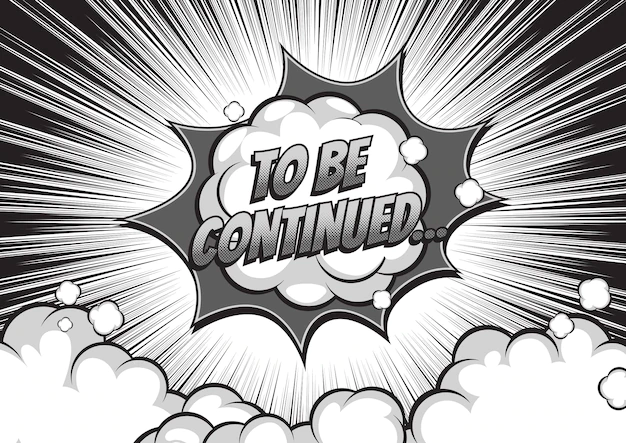

## Literature

[1] K. Shoemake, 1985, *Animating rotation with quaternion **curves*, *ACM SIGGRAPH Computer Graphics*

[2] D. Eberly: *Quaternion Algebra and **Calculus, *[www.geometrictools.com](http://www.geometrictools.com/)

[3] H. Lipkin, J. Duffy, 1985, *On the Geometry of Orthogonal and Reciprocal Screws.*